% solving odes

help ode45

 ode45  Solve non-stiff differential equations, medium order method.
    [TOUT,YOUT] = ode45(ODEFUN,TSPAN,Y0) integrates the system of
    differential equations y' = f(t,y) from time TSPAN(1) to TSPAN(end)
    with initial conditions Y0. Each row in the solution array YOUT
    corresponds to a time in the column vector TOUT. 
      * ODEFUN is a function handle. For a scalar T and a vector Y,
        ODEFUN(T,Y) must return a column vector corresponding to f(t,y).
      * TSPAN is a two-element vector [T0 TFINAL] or a vector with
        several time points [T0 T1 ... TFINAL]. If you specify more than
        two time points, ode45 returns interpolated solutions at the
        requested times.
      * YO is a column vector of initial conditions, one for each equation.
 
    [TOUT,YOUT] = ode45(ODEFUN,TSPAN,Y0,OPTIONS) specifies integration
    option values in the fields of a structure, OPTIONS. Create the
    options

We're solving van der pol eqution

d2 x / dt2 = mu(1 - x^2)(dx / dt) - x

convert to a first order system

dx / dt = v

dx2 / dt2 = dv/dt

v’ = mu(1 - X^2)v - x

mu = 3

mu = 3

f = @(t, y) [y(2); mu*(1 - y(1)^2)*y(2) - y(1)];

[T, Y] = ode45(f, [0 12], [1;1])

T =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.3004
    0.3998
    0.4993
    0.5987
    0.6801


Y =     1.0000    1.0000
    1.0488    0.9412
    1.0943    0.8671
    1.1358    0.7809
    1.1726    0.6861
    1.2309    0.4892
    1.2699    0.2982
    1.2910    0.1278
    1.2965   -0.0138
    1.2914   -0.1088


First column is going to be T's, which wont' be evenly spaced.

Next two columns will be the Y's: y1 and y2.

figure
plot(Y(:, 1), Y(:, 2), "."), grid on

figure

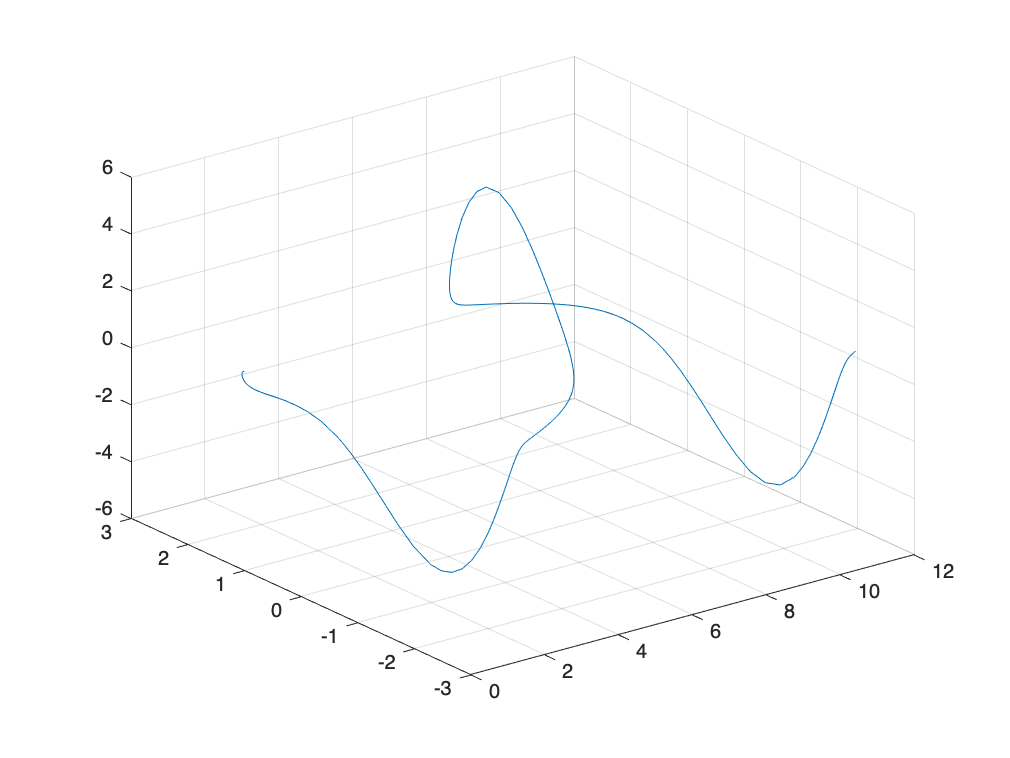

figure
plot3(T, Y(:, 1), Y(:, 2)), grid on

figure

hold on
plot(T, Y(:, 1))
plot(T, Y(:, 2))

*Models for interacting populations:*

*    Here we are thinking of chemical or biological/ecological interactions. In chemistry two populations can interact to form a third species. In biology interactions can lead to a probability of death or of reproduction. The basic assumption is that the rate (per unit time) of interactions is proportional to the concentration of each of the populations involved. Hence we get terms like αxy for x and y or βx² for a population interacting with itself or, in a chemical reaction like H+H+O=H₂O, a term like *$\gamma$*x²y where x,y are concentrations ( of H and O respectively) and α.β,γ are proportionality constants. Here are some models:*

**Fish and Shark Model**

Fish and sharks:


$$\frac{dF}{dt}=F(a-bF-cS)$$
    

Terms: fish growth, logistic term (limits population growth), fish/shark encounters

No sharks, $F' = F(a - bF)$, goes to equilibrium


$$\frac{dS}{dt}=S(-k+\lambda F)$$


Terms: shark death, shark predation

If we set $b=0$ we arrive at the Lotka-Volterra equations:


$$\frac{dF}{dt}=F(a-cS)$$
    


$$\frac{dS}{dt}=S(-k+\lambda F)$$


*In either case we have a system of two first order autonomous ODE's (autonomous means that t does not appear explicitly)*

*In any such autonomous system, of the form *$x'=f(x)$* where *$x$* is a vector of variables, we look for an equilibirum solution *$x_e$* that satisfies *$f(x_e)=0$* since *$x'=0$* if we start with *$x=x_e$*In the case of the Lotka-Volterra equations, we have *$S_e=a/c, F_e=k/\lambda$*. *

*Analysis of Lotka-Volterra solutions*

*This system has periodic solutions that are closed curves in "phase space", namely the F-S plane. If we eliminate *$t$* by dividing, we are led to*

Dividing the fish by the shark model kills the dts:


$$\frac{dF}{dS}=\frac{F(a-cS)}{S(-k+\lambda F)}$$
   

You isolate the F's and S's and the integrate both sides

$cS-a\log S+\lambda F-k\log F=C$ for a constant C

$\frac{e^{cS}}{S^a}\frac{e^{\lambda F}}{F^k}=K$ for a positive constant K. 

Now, we're gonna plot the x/y equilibrium as a function of K

*These are in fact level curves which are closed curves - so the behavior of the populations is periodic.*

Matlab: We show the closed curves $\frac{e^{cS}}{S^a}\frac{e^{\lambda F}}{F^k}=K$ in the (S,F) plane by looking for the level curves of $f(x,y)=\frac{e^{cx+\lambda y}}{x^ay^b}$

c=.2;lambda=.5;a=.6;k=1.2;  %just make up some numbers
%x=shark pop, y=fish
F=@(x,y) exp(c*x+lambda*y)./(x.^a.*y.^k);  %F=k are the trajectories
%equilbrium  (3,2.4)
xe=3;ye=2.4;
[X,Y]=meshgrid(.1:.01:10,.1:.01:6);
Z=F(X,Y);
figure
surf(X,Y,Z)
shading flat %gets rid of grid
colormap(rand(200,3));
axis([0 10 0 6 0 3])
hold on
plot3(xe,ye,F(xe,ye),'k.','MarkerSize',10)

figure
pcolor(X,Y,Z), shading interp
hold on
plot3(xe,ye,F(xe,ye),'k.','MarkerSize',10)
colormap(rand(200,3));

**Species competing for resources **- competitive exclusion principle

        
$$\frac{dx}{dt}=x(a-bx-ky)$$


        
$$\frac{dy}{dt}=y(c-dy-\sigma x)$$


This is like a logsitc model, but the logistic term is in both species.

*    You can think of xy as proportional to the number of encounters of the x population with the y population. And you can imagine that in each encounter they are competing for a resource, which encounters tend to decrease both populations, depending on who is successful in obtaining the resource. Similarly, the success of each population is not symmetric in general - one population may be more successful in these encounters than another, hence k,σ are different constants.*

It turns out that for some parameters values this is unstable---there can be multiple isolated equilibria at a given level curve

**Analysis of a 2x2 autonomous system**

*         Our analysis takes place in the so-called "phase plane" of the dependent variables, where t is not explicitly shown. Any point in the phase plane represents an initial value of the variables, and the resulting trajectory is unique and can be graphed. *

*To get an idea of trajectories we can solve the differential equations. However a more primitive method is through a direction field. The vector (dx/dt,dy/dt) is the velocity vector, showing the direction of the trajectory and its speed. A direction field consists of drawing the velocity vector at a grid of points and trying to visualize the flow. *

*We'll introduce competition among the fish by introducing the parameter b.*


$$\frac{dS}{dt}=S(-k+\lambda F)$$



$$\frac{dF}{dt}=F(a-bF-cS)$$
    

Equilibrium:

Boring one, S = F = 0

- happens when there are no sharks, boring

- we might be curious if this is a stable solution though

Solve for $\lambda F = k$

- 
$$F_e = {k \over \lambda}$$


- 
$$S_e = - {a - bF_e \over c}$$


One thing you might do is solve for when F' or S' is negative or positive as a function of the parameters etc. This could tell you if something is going to zero/infinity/stuff like that

%try b=.3 later
b=.1;c=.2;lambda=.5;a=.6;k=1.2; 
[a b c k lambda]
%    0.6000    0.3000    0.2000    1.2000    0.5000

ans =    0.600000000000000   0.100000000000000   0.200000000000000   1.200000000000000   0.500000000000000


%now introduce fish competition
%x'=x*(-k+lambda*y); y'=y*(a-c*x-by)
ye=k/lambda %equilibrium points  
xe=(a-b*ye)/c

ye =    2.400000000000000


close all

xe =    1.800000000000000


%now for the direction field - first create a grid of points
[X,Y]=meshgrid(0:.2:4,0:.2:5); %usually use capital letter for arrays
U=X.*(-k+lambda*Y);  %dx/dt
V=Y.*(a-b*Y-c*X); %dy/dt
%U is array of horizontal components, V vertical
quiver(X,Y,U,V,5);hold on,plot(xe,ye,'r.','MarkerSize',10)
grid on %we plotted the equilibriumm

Note also that there are equilibria on the boundary. If x=0, then x'=0 and y'=0 at a/b; and if y=0 then y'=0 and then x'=0 at x=0 (the sharks die off). 

Trajectories:

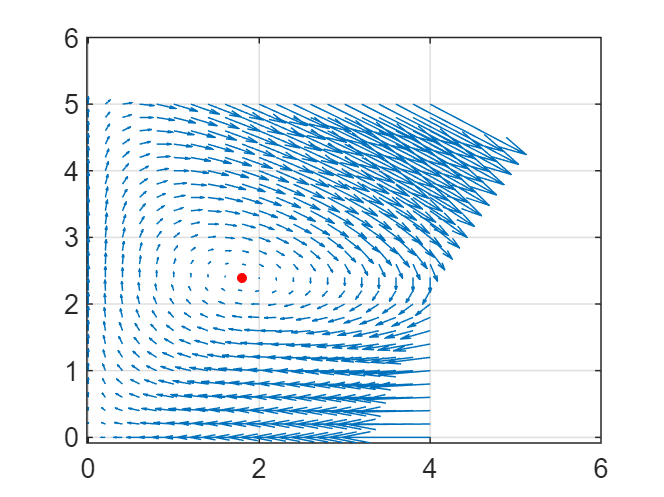

a,b,c,k,lambda

These can be computed using Matlab's ode45.m function, based on the general form x'=f(t,x). So here's an example using b=.3. Note that x=[x(1);x(2)] here - it's a vector

b=.1;c=.2;lambda=.5;a=.6;k=1.2; 

a =    0.600000000000000


b =    0.100000000000000


c =    0.200000000000000


k =    1.200000000000000


lambda =    0.500000000000000


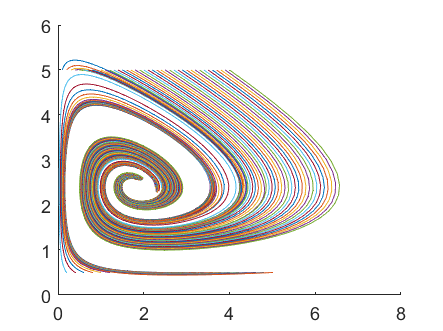

f=@(t,x) [x(1).*(-k+lambda*x(2));x(2).*(a-b*x(2)-c*x(1))];
figure,hold on
for x1=.1:.1:4
[T,X]=ode45(f,0:.1:20,[x1;5]);
plot(X(:,1),X(:,2))
end
pause
for x1=.2:.2:5
    [T,X]=ode45(f,0:.1:20,[x1;.5]);
    plot(X(:,1),X(:,2))
end

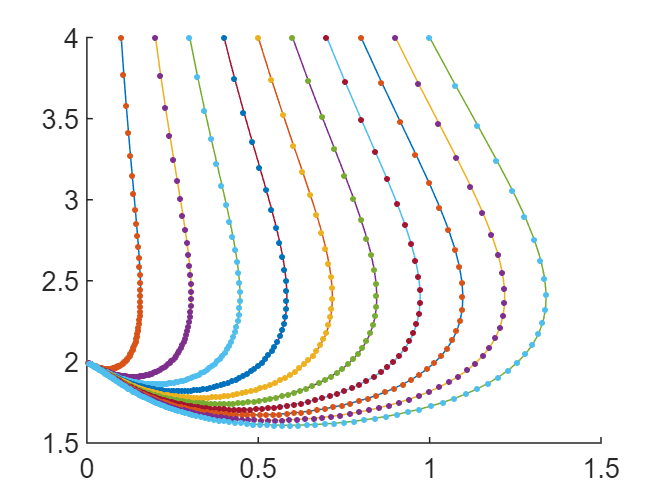

figure
plot(T,X(:,1),T,X(:,2)) %just the last trajectory, x1=1
b=.3;c=.2;lambda=.5;a=.6;k=1.2; 
f=@(t,x) [x(1).*(-k+lambda*x(2));x(2).*(a-b*x(2)-c*x(1))];
figure,hold on
for x1=.1:.1:1
[T,X]=ode45(f,0:.1:20,[x1;4]);

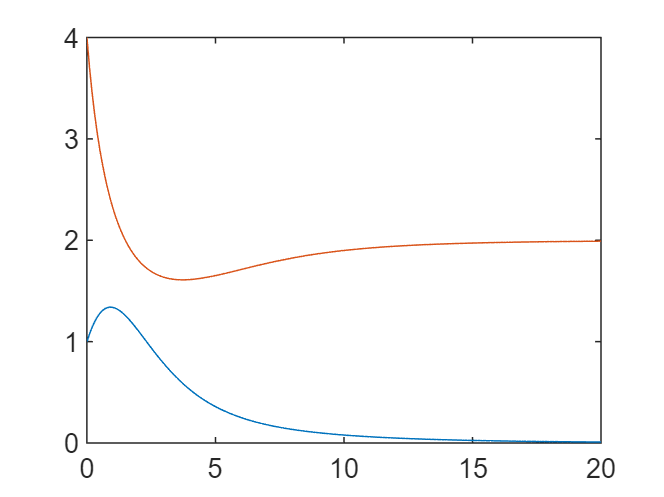

plot(X(:,1),X(:,2),X(:,1),X(:,2),'.')
end
figure


% this shows sharks and fish over time
plot(T,X(:,1),T,X(:,2)) %just the last trajectory, x1=1

Pretty clearly what happens is that the sharks die off and all the trajectories converge to the equilibrium at (0,ye)=(0,a/b)

**Linearization**: determining what happens near an equilibrium

*If our system is *$x'=f(x,y);y'=g(x,y)$* and *$(x_e,y_e)$* is an equilibrium where *$x'=f(x_e,y_e)=0;y'=g(x_e,y_e)=0$* then near the equilibrium *$f,g$* we can consider *$x=x_e+u,y=y_e+v$* and have the linear approximation about an equilibrium:  *

So, we're gonna consider small perturbations about the equilibrium and ask what happens to the derivatives f and g.

Approximation using a plane. Note the f(x, y) and g(x, y) are zero here.


$$f(x_e+u,y_e+v)\approx f_x(x_e,y_e)u+f_y(x_e,y_e)v$$



$$g(x_e+u,y_e+v)\approx g_x(x_e,y_e)u+g_y(x_e,y_e)v$$


so in terms of the deviations u,v we have


$$u'=f_x(x_e,y_e)u+f_y(x_e,y_e)v$$



$$v'=g_x(x_e,y_e)u+g_y(x_e,y_e)v$$


Matrix of this^

A = [[f_x, f_y], [g_x, g_y]]

x = [u, v]^T

x' = Ax

*And this is a constant coefficient sytem for the deviations u,v. The behavior of the trajectories near the equilibrium (so the deviations u,v are small) is determined by the eigenvalues and eigenvectors of the matrix of coefficients. For our Shark/Fish system we have*

We take the eigenvectors of A to sole this, for general A, we could get

- two real distinct solutions: we do the c_i exp(\lambda_i t)V_i - geometric interpretation of this

-         maybe one of the c_i's is zero, the you're moving strait away (towards) this line

$x'=x(-k+\lambda y); y'=y(a-cx-by)$ resulting in a linearization about equilibrium of (verify yourself!)


$$\frac{du}{dt}=\lambda x_ev$$



$$\frac{dv}{dt}=-cy_e u -by_ev$$


We'll use our values here

a=0.6000,b=0.1000,  c=0.2000,k=1.2000, lambda=0.5000

a =    0.600000000000000


b =    0.100000000000000


c =    0.200000000000000


k =    1.200000000000000


lambda =    0.500000000000000


ye=k/lambda %equilibrium pints

ye =    2.400000000000000


xe=(a-b*ye)/c

xe =    1.800000000000000


A=[ 0 lambda*xe;-c*ye -b*ye]

A =                    0   0.900000000000000
  -0.480000000000000  -0.240000000000000


[V,D]=eigs(A)

V =   0.807572853087248 + 0.000000000000000i  0.807572853087248 + 0.000000000000000i
 -0.107676380411633 + 0.579855054352354i -0.107676380411633 - 0.579855054352354i


D =  -0.120000000000000 + 0.646219776856141i  0.000000000000000 + 0.000000000000000i
  0.000000000000000 + 0.000000000000000i -0.120000000000000 - 0.646219776856141i


These are complex eigenvalues, negative real part so the trajectory of (u,v) is a spiral into the origin; in phase space (x,y) spiral into the equilibrium.

If you want to use this information to plot linearized trajectories, you might use the formula:

$x\left(t\right)=V\left\lbrack \begin{array}{cc}
e^{\lambda_1 t}  & 0\\
0 & e^{\lambda_2 t} 
\end{array}\right\rbrack V^{-1} x_0$ where V is the matrix of eigenvectors and the lambda's come from D. However, for graphical purposes and ease of computation, we'll just use ode45.m to calculate and plot trajectors of even the linearization. 

Let's return to b=.3 and our direction field above and plot the linearization. This repeats some of the calculations above

a=0.6000,b=0.1000,  c=0.2000,k=1.2000, lambda=0.5000;

a =    0.600000000000000


b =    0.100000000000000


c =    0.200000000000000


k =    1.200000000000000


%    0.6000    0.3000    0.2000    1.2000    0.5000
%now introduce fish competition
%x'=x*(-k+lambda*y); y'=y*(a-c*x-by)
ye=k/lambda %equilibrium points  

ye =    2.400000000000000


xe=(a-b*ye)/c

xe =    1.800000000000000


close all
%now for the direction field - first create a grid of points
[X,Y]=meshgrid(0:.2:4,0:.2:5); %usually use capital letter for arrays
U=X.*(-k+lambda*Y);  %dx/dt
V=Y.*(a-b*Y-c*X); %dy/dt
%U is array of horizontal components, V vertical
quiver(X,Y,U,V,5);hold on,plot(xe,ye,'r.','MarkerSize',10)
grid on %we plotted the equilibrium
A=[ 0 lambda*xe;-c*ye -b*ye]

A =                    0   0.900000000000000
  -0.480000000000000  -0.240000000000000


f=@(t,x) A*x

f = function_handle with value:
    @(t,x)A*x


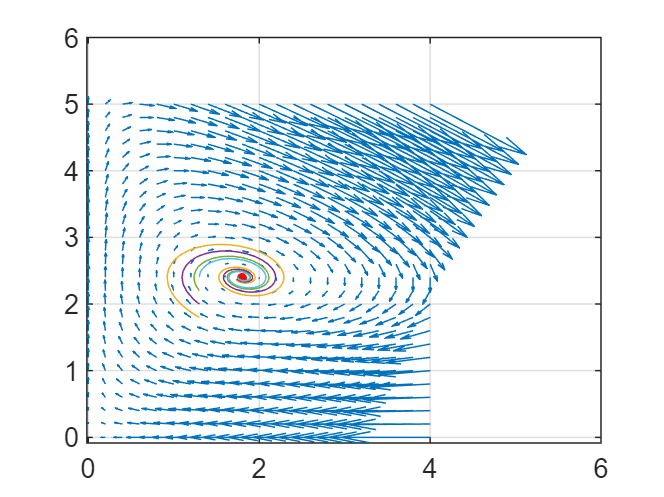

for v0=-.6:.2:0
    u0=-.5;
    [T,X]=ode45(f,[0 20],[u0;v0]);
    plot(xe+X(:,1),ye+X(:,2)) %note that X contains deviations u,v off xe,ye
end

Finally, we'll plot the trajectories along with the direction field. 

a=0.6000,b=0.1000,  c=0.2000,k=1.2000, lambda=0.5000;

a = 0.6000

b = 0.1000

c = 0.2000

k = 1.2000

[a b c k lambda]

ans =     0.6000    0.1000    0.2000    1.2000    0.5000


%now introduce fish competition
%x'=x*(-k+lambda*y); y'=y*(a-c*x-by)
ye=k/lambda %equilibrium points  

ye = 2.4000

xe=(a-b*ye)/c

xe = 1.8000

close all
%now for the direction field - first create a grid of points
[X,Y]=meshgrid(0:.2:4,0:.2:5); %usually use capital letter for arrays
U=X.*(-k+lambda*Y);  %dx/dt
V=Y.*(a-b*Y-c*X); %dy/dt
%U is array of horizontal components, V vertical
quiver(X,Y,U,V,5);hold on,plot(xe,ye,'r.','MarkerSize',10)
grid on %we plotted the equilibrium
ye=k/lambda %equilibrium points

ye = 2.4000

xe=(a-b*ye)/c

xe = 1.8000

f=@(t,x) [x(1).*(-k+lambda*x(2));x(2).*(a-b*x(2)-c*x(1))];
for y0=.5:.25:1.5
    x0=2;
    [T,X]=ode45(f,[0 20],[x0;y0]);
    plot(X(:,1),X(:,2))
end

**Competitive Exclusion Model**


$$x' = x(a - bx - ky)$$



$$y' = y(c - dy - \sigma x)$$


solve for equilibira

"external" equilibira

- (0, 0)

- (0, c/d)

- (a / b, 0)

"internal"

- solve both equations

- 
$$bx + ky = a$$


- 
$$\sigma x + dy = c$$


- these intersect at the internal equilibrium

a = 0.01

a = 0.0100

b = 0

b = 0

c = 0.01

c = 0.0100

d = 0

d = 0

k = 0

k = 0

sigma = 0

sigma = 0


[xm, ym] = meshgrid(0:2:0.1, 0:2:0.1)

xm = 0

ym = 0


dx = xm*(a - b*xm - k*ym)

dx = 0

dy = ym*(c - d*ym - sigma*xm)

dy = 0

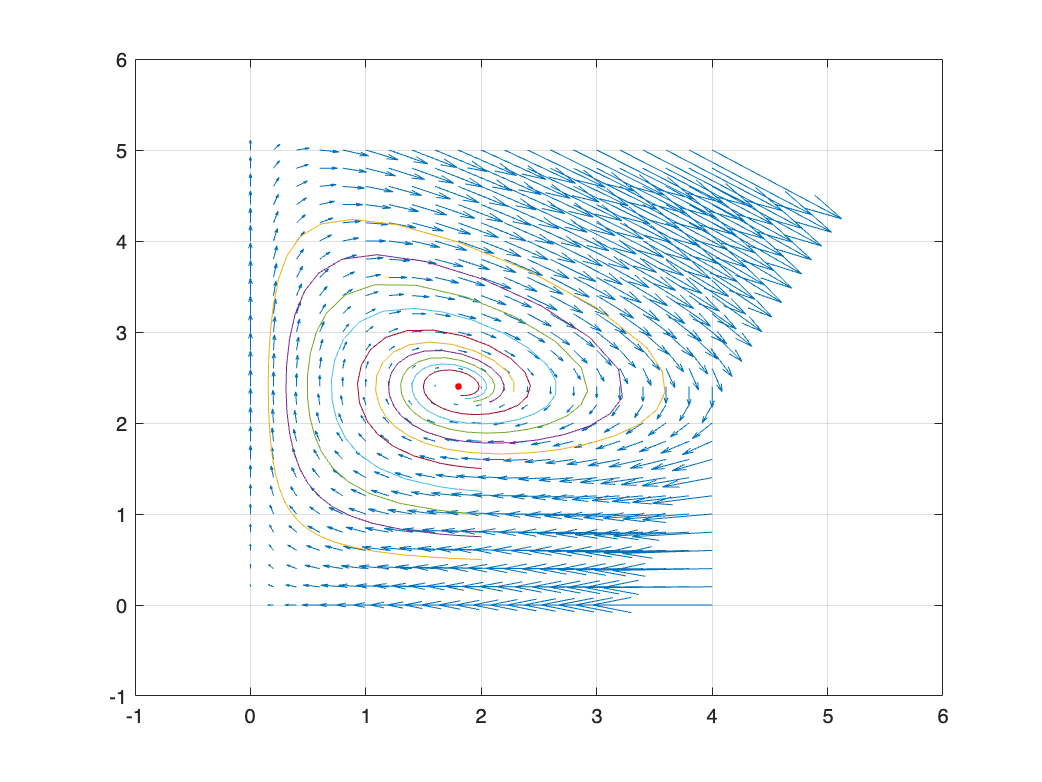


quiver(dx, dy)

figure,hold on
A=[.4 .6;1 1/4];
b=[1.2;1];
xe=A\b, plot(xe(1),xe(2),'.','MarkerSize',10)

xe =     0.6000
    1.6000


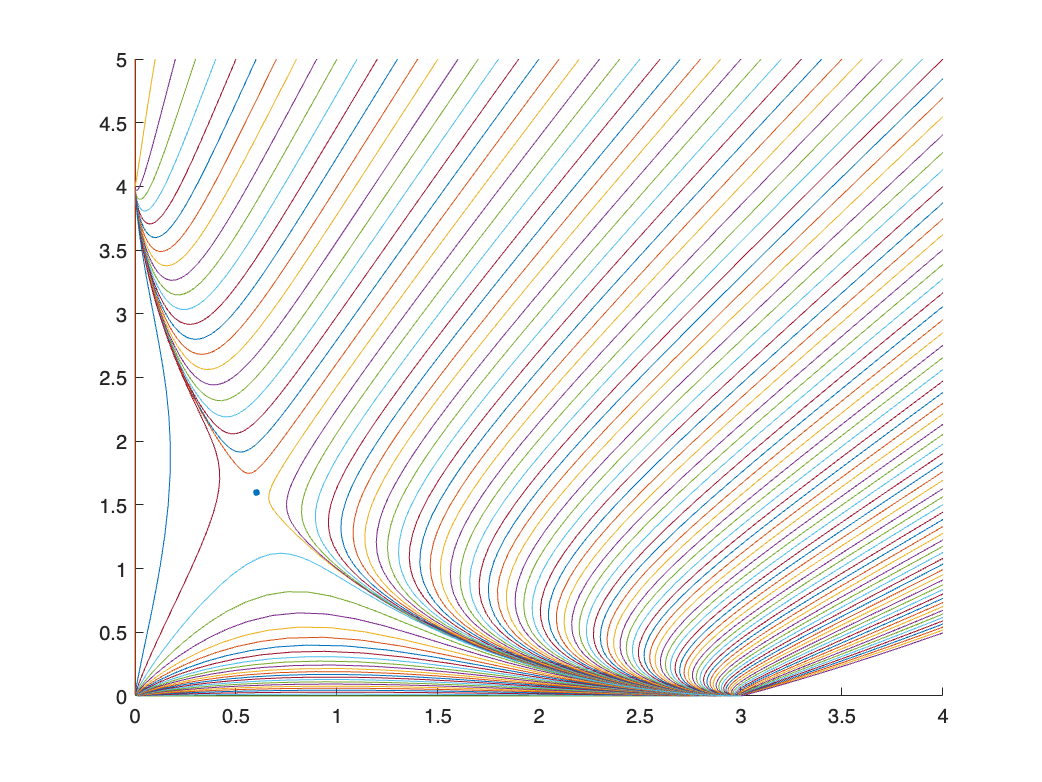

f=@(t,x) diag(x)*(b-A*x);
for t=0:.1:10 
    [T,X]=ode45(f,[0 20],[t;5]);
    plot(X(:,1),X(:,2))
    axis([0 4 0 5])  
end
for t=0:pi/50:pi/2
    x0=.01*[cos(t);sin(t)];
    [T,X]=ode45(f,[0 20],x0);
    plot(X(:,1),X(:,2))
    axis([0 4 0 5])  
end